### Comparing our measurements of dorsal tongue fluorescence to other published data

We compare our fluorescence measurements of tongue and, in some cases, lower lip to fluorescence measurements of fluorescence published for same locations

%{
cd /Users/joyce/Github/isetcam; addpath(genpath(pwd));
cd /users/joyce/Github/oraleye/; addpath(genpath(pwd));
cd /users/joyce/Github/isetfluorescence/; addpath(genpath(pwd));
cd /users/joyce/Github/oe_tongue_lip/; addpath(genpath(pwd));
%}

wave = 500:700;

### Tongue (deVeld)

de Veld, D. C., Skurichina, M., Witjes, M. J., Duin, R. P., Sterenborg, D. J., Star, W. M., & Roodenburg, J. L. (2003).  Autofluorescence characteristics of healthy oral mucosa at different anatomical sites. Lasers in Surgery and Medicine: The Official Journal of the American Society for Laser Medicine and Surgery, 32(5), 367-376

Figure 4, "Mean autofluorescence spectra of healthy oral mucosa obtained at four representative locations, excitation wavelength 405 nm" , cheek mucosa and the dorsal side of the tongue

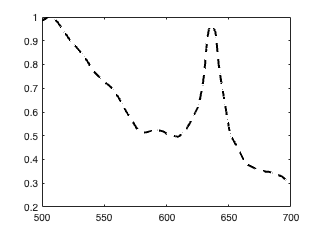

tongue = ieReadSpectra('TongueVeld2003.mat',wave);
ieNewGraphWin;
plot(wave,tongue/max(tongue(:)),'k--','lineWidth',2); hold on;

### Tongue (Mallia)

Mallia, R. J., Thomas, S. S., Mathews, A., Kumar R, R., Sebastian, P., Madhavan, J., & Subhash, N. (2008). Laser‐induced autofluorescence spectral ratio reference standard for early discrimination of oral cancer. *Cancer*, *112*(7), 1503-1512.

Fig 3 " LIAF emission spectra from oral mucosa were recorded in the 420–720 nm spectral range on a miniature fiberoptic spectrometer from 14 anatomical sites of 35 healthy volunteers and 91 sites of 44 patients, with **excitation at 404 nm** from a diode laser."

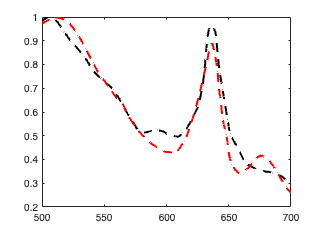

tongue = ieReadSpectra('DorsalTongueMallia2008.mat',wave);
plot(wave,tongue/max(tongue(:)),'r--','lineWidth',2); hold on;

## Read a couple of raw data sets

This is the database of raw measurements.

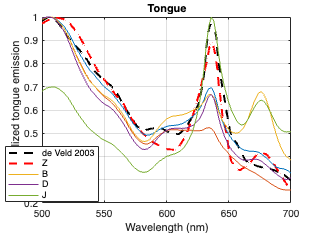

[T,dataDir] = oeDatabaseCreate;

files405Z = ieTableGet(T,'subject','Z','substrate','tongue','e wave',405,'e level',980,'return','files');
files405B = ieTableGet(T,'subject','B','substrate','tongue','e wave',405,'e level',980,'return','files');
files405D = ieTableGet(T,'subject','D','substrate','tongue','e wave',405,'e level',980,'return','files');
files405J = ieTableGet(T,'subject','J','substrate','tongue','e wave',405,'e level',980,'return','files');
tongueFiles = cat(1,files405Z,files405B,files405D,files405J);

tongueData = zeros(numel(wave),numel(tongueFiles));

for ii=1:numel(tongueFiles)
    data = ieReadSpectra(fullfile(dataDir,tongueFiles{ii}),wave); 
    tongueData (:,ii) = data(:);
    plot(wave,data/max(data(:))); hold on;
end
legend({'de Veld 2003','Z','B','D','J'});
title('Tongue');
xlabel('Wavelength (nm)'); ylabel('Normalized tongue emission'); grid on;